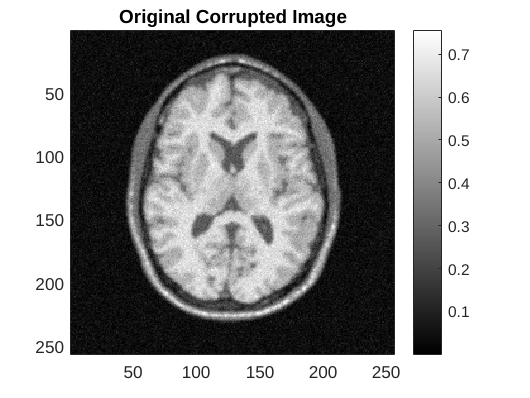

load('assignmentSegmentBrainGmmEmMrf.mat');

Y = imageData;
M = imageMask;
K = 3;





minimum = min(Y(:));
Y = Y - minimum;
maximum = max(Y(:));

X = zeros(size(Y, 1), size(Y, 2));

positions = and(Y <= maximum, M == 1);
X(positions) = 3;

positions = and(Y <= 2 * maximum / 3, M == 1);
X(positions) = 2;

positions = and(Y <= maximum / 3, M == 1);
X(positions) = 1; 






u = zeros(1, K);
s = zeros(1, K);
beta = 0.33;
   
for label = 1:K
    positions = X == label;
    u(1, label) = mean(Y(positions));
    s(1, label) = std(Y(positions));
end

%% GMM EM MRF With beta = 0.36
% Gaussian Mixture Model, with Expectation Maximisation with potential beta
% equal to 0.36

%[L, G] = getEMLabels(Y, M, K, X, u, s, beta, 1);
show_values = 1;
[r, c] = size(Y);
gr1 = zeros(1,25);
   
   Gamma = zeros(r, c, K);
   membership_beta = beta;
   
   for count = 1:25
       [X, u, s, zz] = getIcmLabels( Y, M, K, X, u, s, beta, show_values);
       gr1(1,count) = zz;
       for i = 2:r-1
           for j = 2:c-1
               if (M(i, j) == 0)
                   continue;
               end
                   
               memberships = zeros(1, K);
               for x = 1:K
                   prior = getPrior(X, x, i, j, M, membership_beta);
                   posterior = exp(- ( 1 - membership_beta ) * (Y(i, j) - u(1, x))^2 / (2 * s(1, x) * s(1, x)));
                   memberships(1, x) = prior * posterior;
               end
               
                memberships = memberships ./ sum(memberships(:));
                if (sum(isnan(memberships)) > 0)
                    Gamma(i,j,:) = Gamma(i,j,:);
                else
                    Gamma(i,j,:) = memberships;
                end
               
           end
       end
       
       for label = 1:K
           D = sum(sum(Gamma(:, :, label)));
           S = Gamma(:, :, label) .* Y(:, :);
           S = sum(S(:));
           u(1, label) = S / D;

           S = (Y(:, :) - u(1,label)).^2;
           S = Gamma(:, :, label) .* S;
           S = sum(S(:));
           s(1, label) = sqrt(S / D);
       end
   end





showImage(imageData, 'Original Corrupted Image');

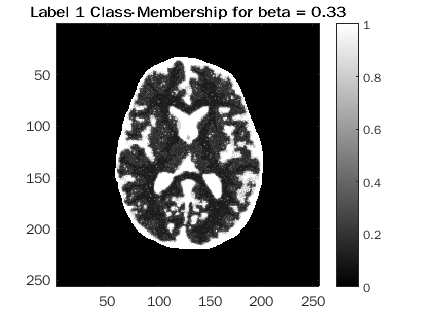

showImage(Gamma(:, :, 1), 'Label 1 Class-Membership for beta = 0.33');

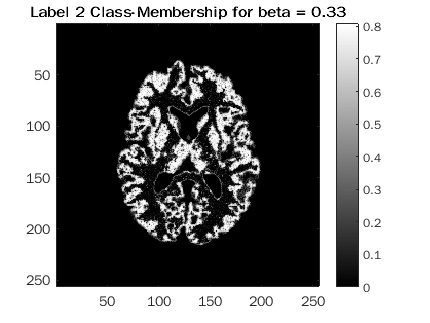

showImage(Gamma(:, :, 2), 'Label 2 Class-Membership for beta = 0.33');

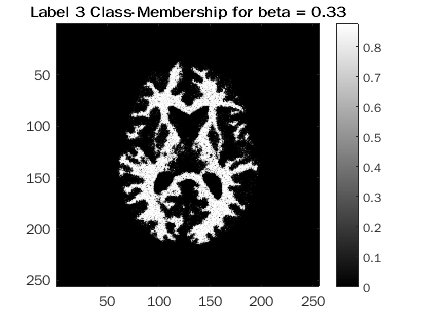

showImage(Gamma(:, :, 3), 'Label 3 Class-Membership for beta = 0.33');

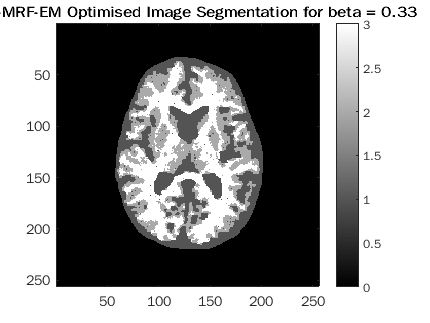

showImage(X, 'GMM-MRF-EM Optimised Image Segmentation for beta = 0.33');

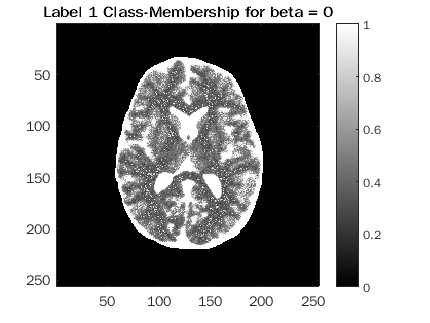


%% GMM EM MRF With beta = 0
% Gaussian Mixture Model, with Expectation Maximisation with no MRF

%[L, G] = getEMLabels(Y, M, K, X, u, s, 0, 1);

show_values = 1;
beta = 0;
[r, c] = size(Y);
gr2 = zeros(1,25);
   
   Gamma = zeros(r, c, K);
   membership_beta = beta;
   
   for count = 1:25
       [X, u, s, zz] = getIcmLabels( Y, M, K, X, u, s, beta, show_values);
       gr2(1,count) = zz;
       for i = 2:r-1
           for j = 2:c-1
               if (M(i, j) == 0)
                   continue;
               end
                   
               memberships = zeros(1, K);
               for x = 1:K
                   prior = getPrior(X, x, i, j, M, membership_beta);
                   posterior = exp(- ( 1 - membership_beta ) * (Y(i, j) - u(1, x))^2 / (2 * s(1, x) * s(1, x)));
                   memberships(1, x) = prior * posterior;
               end
               
                memberships = memberships ./ sum(memberships(:));
                if (sum(isnan(memberships)) > 0)
                    Gamma(i,j,:) = Gamma(i,j,:);
                else
                    Gamma(i,j,:) = memberships;
                end
               
           end
       end
       
       for label = 1:K
           D = sum(sum(Gamma(:, :, label)));
           S = Gamma(:, :, label) .* Y(:, :);
           S = sum(S(:));
           u(1, label) = S / D;

           S = (Y(:, :) - u(1,label)).^2;
           S = Gamma(:, :, label) .* S;
           S = sum(S(:));
           s(1, label) = sqrt(S / D);
       end
   end

showImage(Gamma(:, :, 1), 'Label 1 Class-Membership for beta = 0');

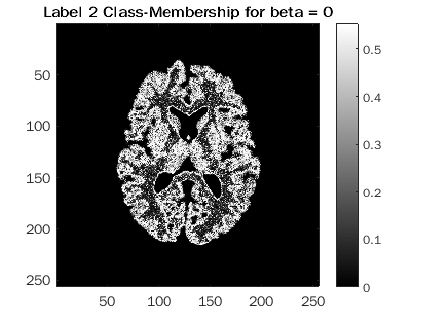

showImage(Gamma(:, :, 2), 'Label 2 Class-Membership for beta = 0');

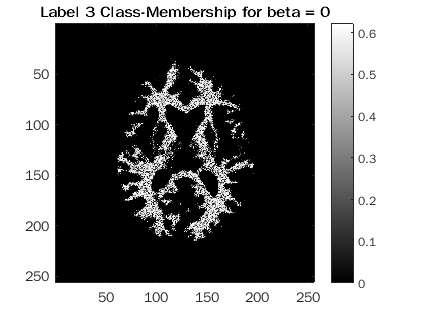

showImage(Gamma(:, :, 3), 'Label 3 Class-Membership for beta = 0');

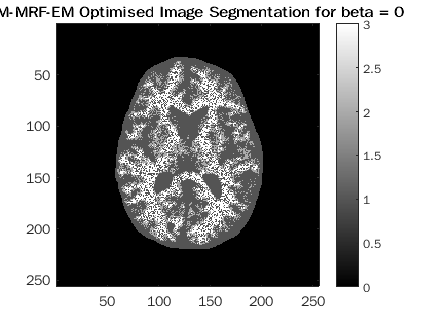

showImage(X, 'GMM-MRF-EM Optimised Image Segmentation for beta = 0');


u

u =     0.4746    0.5660    0.6474


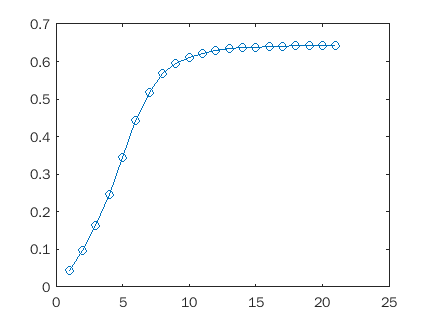

       figure; plot(gr1(5:25),'-o');

       figure; plot(gr2(5:25),'-o');

function [ out ] = getPrior( X, x, i, j, M, beta)
    diff_count = 0;
    if M(i - 1, j) == 1
        diff_count = diff_count + (X(i - 1, j) ~= x);
    end
    if M(i + 1, j) == 1
        diff_count = diff_count + (X(i + 1, j) ~= x);
    end
    if M(i, j - 1) == 1
        diff_count = diff_count + (X(i, j - 1) ~= x);
    end
    if M(i, j + 1) == 1
        diff_count = diff_count + (X(i, j + 1) ~= x);
    end

    out = exp(-diff_count * beta);
end


function showImage( image, image_title )
if nargin < 2
    image_title = 'Image Title';
end

figure;
    my_num_of_colors = 200;
    my_color_scale = [ [0:1/(my_num_of_colors-1):1]' , ...
        [0:1/(my_num_of_colors-1):1]' , [0:1/(my_num_of_colors-1):1]' ];
    imagesc (single (image));
    title(image_title);
    colormap (my_color_scale);
    colormap gray;
    daspect ([1 1 1]);
    axis tight;
    colorbar;
end

function [X, u, s, zz] = getIcmLabels( Y, M, K, X, u, s, beta, show_values )
   [r, c] = size(Y);
   X_c = X;
   original_cummulative_value = 0;
   cummulative_value = 0;
   for count = 1:10
       for i = 2:r-1
           for j = 2:c-1
               if (M(i, j) == 0)
                   continue;
               end
                   
               x = X(i, j);
               original_prior = getPrior(X, x, i, j, M, beta);
               original_posterior = exp(- ( 1 - beta ) * (Y(i, j) - u(1, x))^2 / (2 * s(1, x) * s(1, x)));
               original_cummulative_value = original_cummulative_value + original_prior * original_posterior;
               
               values = zeros(1, K);
               for x = 1:K
                   prior = getPrior(X, x, i, j, M, beta);
                   posterior = exp(- ( 1 - beta ) * (Y(i, j) - u(1, x))^2 / (2 * s(1, x) * s(1, x)));
                   values(1, x) = posterior * prior;
               end
               [value, index] = max(values);
               cummulative_value = cummulative_value  - log(value);
               X_c(i, j) = index;
           end
       end
       X = X_c .* M;
   end
   
   if show_values == 1
%        figure; plot(cummulative_value,'-o');
%        figure; plot(original_cummulative_value,'-o');
    zz = -log(value);
%     display(sprintf('ICM : P(x | y, beta, theta) : %d => %d', original_cummulative_value, cummulative_value));
   end
   
   
end